# Script to compute GMT pier vibration transfer functions

This script combines a state-space model representing the GMT's structural dynamics, the mount axes feedback controller transfer functions, optical sensitivity matrices, and rejection transfer functions to obtain the transfer function between accelerations of a node representing the telescope pier and the optical structure (mount) interface and the wavefront error. The goal is to provide a transfer function representing the telescope's sensitivity to pier vibrations.

## Preamble

clearvars;

plotInLabel = {'F_x','F_y','F_z','M_x','M_y','M_z'};
plotOutLabel = {'T_x','T_y','T_z','R_x','R_y','R_z'};
plotUnitstr = {'N','N','N','Nm','Nm','Nm'};

reposFIGs = [1,3,5,2,4,6];

- Radians to mili arc second conversion constant

rad2mas = (180/pi * 3600 * 1000);

- Root of the sum of squared values function

rss = @(x,dir)sqrt(sum(x.^2,dir));

- Set telescope structural dynamics damping

sysDamp = 0.02;

## Load Integrated Model Subsystems

Structural model folder

ModelFolder = '20221208_1220_MT_mount_zen_30_m1HFN_FSM__groundTF';

### Telescope Structural Dynamics Model

To assess the impact of pier vibration, a model of the telescope was prepared with the following features, based on the large mass method outlined in chapters 8.6 and 8.7 of the “NX Nastran 9.0 Basic Dynamic Analysis User Guide”.

The pier was replaced by a single mass at the center of the pier top surface. The figure below highlights that mass element in yellow. This node may be referred to as the pier interface. This mass is rigidly connected to the entire azimuth track, essentially making the track rigid. The mass and moment of inertia of the single mass are $10^6$ times larger than the corresponding properties of the telescope. Because of this mass imbalance, the displacement, velocity, and acceleration of the single mass are essentially independent of the dynamics of the telescope and can be controlled to a high accuracy by applying input forces and moments to the pier interface such that the input forces are computed by multiplying the desired acceleration by the single mass. To enable static evaluations the 6 degrees of freedom of the pier interface are restricted by weak grounded springs that yield 6 eigenfrequencies around 0.01 Hz.

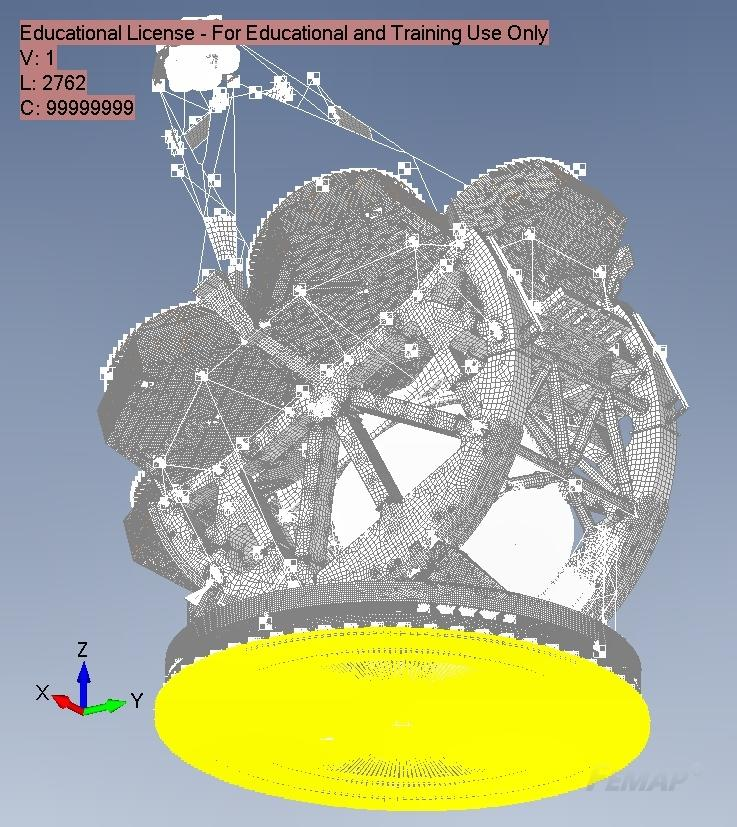

In the frequency domain analysis, we do not consider the first six state-space model modes, which correspond to the rigid-body motion of the entire telescope.

first_mode = 7;
FileName = fullfile(im.lfFolder,ModelFolder,"modal_state_space_model_2ndOrder.mat");
if(~exist('outputTable','var') || false)
    
    fprintf("Loading modal model parameters from \n%s\n",FileName);
    load(FileName,'inputs2ModalF','modalDisp2Outputs',...
        'eigenfrequencies','inputTable','outputTable');
    % Handle modal paramete
    om0 = eigenfrequencies(first_mode:end)*2*pi;
    proportionalDampingVec = sysDamp*ones(size(eigenfrequencies(first_mode:end)));
    twice_zom = 2*proportionalDampingVec.*om0;
    
    % State-space model matrices
    B = [zeros(size(inputs2ModalF(first_mode:end,:)));...
        inputs2ModalF(first_mode:end,:)];
    C = [modalDisp2Outputs(:,first_mode:end),...
        zeros(size(modalDisp2Outputs(:,first_mode:end)))];
    
    nm = size(inputs2ModalF(first_mode:end,:),1);
    A = sparse([zeros(nm),eye(nm);-diag(om0.^2), -diag(twice_zom)]);
    
    fprintf("The model maximum eigenfrequency is %.5fHz\n",om0(end)/2/pi);
end

Loading modal model parameters from 
/Users/rromano/Workspace/gmt-data/20221208_1220_MT_mount_zen_30_m1HFN_FSM__groundTF/modal_state_space_model_2ndOrder.mat


The model maximum eigenfrequency is 99.99914Hz


### Load optical sensitivity matrices

The optical sensitivity matrices provide a linear approximation of the effect of telescope motion on the image at the exit pupil. There are two linear transformations: $L_\text{TT} \in \mathbb{R}^{14 \times 84}$ and $L_\text{P} \in \mathbb{R}^{7 \times 84}
$, which map the M1 and M2 rigid-body motions vector of the seven segments into segment tip-tilt (TT), and piston at the exit pupil, respectively.

As the telescope structural dynamics model has the M1 & M2 translations and rotations as outputs, the matrix 


$$L_o = \left[ L_\text{TT}^T \ L_\text{P}^T \right]^T$$


is a proxy to assess the effect of external forces (disturbances) on the image quality. The segment TT and piston are further mapped into the wavefront error, as described later.

filename1 = fullfile(im.lfFolder,'LOM-data','lom_tt_dt.mat');
load(filename1,'D_seg_tt');
fprintf('\nTT sensitivity matrix loaded from \n%s\n',filename1);


TT sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/LOM-data/lom_tt_dt.mat


filename2 = fullfile(im.lfFolder,'LOM-data','D_seg_piston_dt.mat');
load(filename2,'D_seg_piston');
fprintf('\nPiston sensitivity matrix loaded from \n%s\n',filename2);


Piston sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/LOM-data/D_seg_piston_dt.mat


### Extract subsystem with relevant inputs and outputs

The telescope structural dynamics model is a crucial element in analyzing the effect of external forces on the GMT's optical degrees of freedom. A subset of the complete structural dynamics model inputs and outputs is sufficient to profile the telescope's sensitivity to vibration sources.

**Subsystem with segment PTT outputs**

Such a subset has the M1&M2 rigid-body motions as outputs and the forces applied to a node (located at the center of the azimuth track) representing the interface between the pier and the telescope optical structure. The telescope model subsystem transfer function $G(j\omega)$ also includes the mount drive torques and the mount axes motions so that the mount positioning feedback control system is incorporated into the results. We embed the optical sensitivity matrices into the obtained model.

% Pier force
pier_in = inputTable{'OSS00_Pier_6F',"indices"}{1};
% MNT drives input indices
mntAZ_in = inputTable{'OSS_AzDrive_Torque',"indices"}{1};
mntEL_in = inputTable{'OSS_ElDrive_Torque',"indices"}{1};
mntGIR_in = inputTable{'OSS_RotDrive_Torque',"indices"}{1};

% SS model input matrix
b = [B(:,pier_in),...
    mean(B(:,mntAZ_in),2), mean(B(:,mntEL_in),2), mean(B(:,mntGIR_in),2)];
nu = size(b,2);

% M1/M2 RBM
m1_out = outputTable{'OSS_M1_lcl','indices'}{1};
m2_out = outputTable{'MC_M2_lcl_6D','indices'}{1};
% MNT enc output indices
mntAZ_out = outputTable{'OSS_AzEncoder_Angle',"indices"}{1};
mntEL_out = outputTable{'OSS_ElEncoder_Angle',"indices"}{1};
mntGIR_out = outputTable{'OSS_RotEncoder_Angle',"indices"}{1};

% SS model output matrix
c = [[D_seg_tt; D_seg_piston]*[C(m1_out,:); C(m2_out,:)];...
    mean(C(mntAZ_out,:),1);mean(C(mntEL_out,:),1);mean(C(mntGIR_out,:),1)];
ny = size(c,1);

% Pick selected submatrices and wrap subsystem model into CMM object
comp_name = struct('name','G','shortname',[],'nastran',[],'mfile',[]);
sys_prime = struct('A',A,'B',b,'C',c,'D',zeros(ny,nu),'method',[]);
clear inputs outputs
inputs{1} = struct('name','Pier_6F','indexes',1:6,'ctrace',[]);
inputs{2} = struct('name','MNT_To','indexes',7:nu,'ctrace',[]);
outputs{1} = struct('name','TT','indexes',1:14);
outputs{2} = struct('name','Piston','indexes',15:21);
outputs{3} = struct('name','MNT_Enc','indexes',22:ny);

obj_sys = component_mode_model(comp_name,sys_prime,inputs,outputs);

### Load mount controller transfer functions

Three transfer functions with a PID controller and notch filter terms (structural modes attenuation) compose the optical structure (mount) feedback control model $C_\text{mnt}(j\omega)$. The obtained control system (illustrated in the figure below) matches the performance and robustness requirements described in GMT-REQ-03215 and GMT-DOC-02011.

ctrlFileName = fullfile("/Users/rromano/Workspace/GMT-IMS",...
    'controls_5pt1g_z30_llTT_oad.mat');
load(ctrlFileName,'mount');

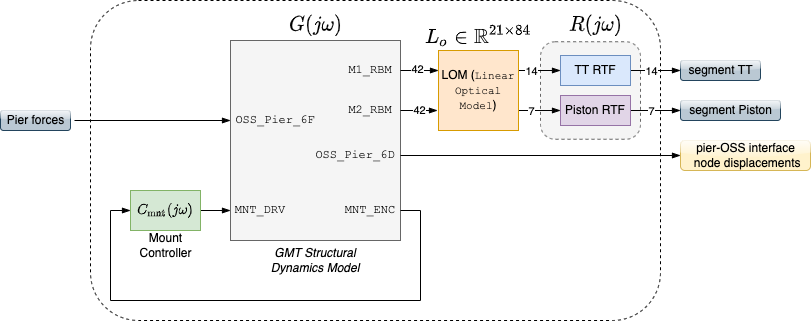

The block $R(j\omega)$ is the optical rejection transfer function used to represent the effect of the wavefront control system. One can perform the analysis considering the Natural Seeing (NS) or the LTAO (default) wavefront control modes.

**Subsystem with pier displacement outputs**

We also take a subsystem model having as outputs the rigid-body motions of the node representing the interface between the pier and GMT's optical structure. That model is considered just for verification purposes.

% Pier node displacements
pier_out = outputTable{'OSS00_Pier_6D','indices'}{1};

% SS model output matrix
c_pier_mnt = [C(pier_out,:);...
    mean(C(mntAZ_out,:),1);mean(C(mntEL_out,:),1);mean(C(mntGIR_out,:),1)];
ny_ = size(c_pier_mnt,1);

% Pick selected submatrices and wrap subsystem model into CMM object
comp_name = struct('name','G','shortname',[],'nastran',[],'mfile',[]);
sys_prime = struct('A',A,'B',b,'C',c_pier_mnt,'D',zeros(ny_,nu),'method',[]);
clear inputs outputs
inputs{1} = struct('name','Pier_6F','indexes',1:6,'ctrace',[]);
inputs{2} = struct('name','MNT_To','indexes',7:nu,'ctrace',[]);
outputs{1} = struct('name','Pier_6D','indexes',1:6);
outputs{2} = struct('name','MNT_Enc','indexes',6+1:ny_);

obj_pier_mnt = component_mode_model(comp_name,sys_prime,inputs,outputs);

## Frequency responses (FRs)

nw = 2^11+1;
% freq = logspace(log10(0.05), log10(100), nw);
freq = linspace(0.05, 100, nw);
om = freq*2*pi;

**Structural plant frequency response model**

fprintf("Computing model frequency response from %.3g-%.3gHz\n",freq(1),freq(end))

Computing model frequency response from 0.05-100Hz


proper_ss_fr = bode_second_order(obj_sys, om, om0, proportionalDampingVec, 1:nu, 1:ny);
G_fr = frd(proper_ss_fr, om, mount.Ts);

fprintf("\nDone!")


Done!

**Mount Controller + drives FR models**

% Azimuth
az_dtHfb = ss(mount.az.SSdtHfb.A,...
            mount.az.SSdtHfb.B,...
            mount.az.SSdtHfb.C,...
            mount.az.SSdtHfb.D,mount.az.SSdtHfb.Ts);
az_C_fr = frd(az_dtHfb, om);
az_delay_fr = frd(tf(1,1,mount.Ts,'IOdelay',mount.az.delay/mount.Ts), om);
az_drive_fr = frd(mount.az.hDrive, om);

% Elevation
el_dtHfb = ss(mount.el.SSdtHfb.A,...
            mount.el.SSdtHfb.B,...
            mount.el.SSdtHfb.C,...
            mount.el.SSdtHfb.D,mount.el.SSdtHfb.Ts);
el_C_fr = frd(el_dtHfb, om);
el_delay_fr = frd(tf(1,1,mount.Ts,'IOdelay',mount.el.delay/mount.Ts), om);
el_drive_fr = frd(mount.el.hDrive, om);

% GIR
gir_dtHfb = ss(mount.gir.SSdtHfb.A,...
            mount.gir.SSdtHfb.B,...
            mount.gir.SSdtHfb.C,...
            mount.gir.SSdtHfb.D,mount.gir.SSdtHfb.Ts);
gir_C_fr = frd(gir_dtHfb, om);
gir_delay_fr = frd(tf(1,1,mount.Ts,'IOdelay',mount.gir.delay/mount.Ts), om);
gir_drive_fr = frd(mount.gir.hDrive, om);

**Compute telescope FRF matrix considering the mount feedback control**

if(exist("C_fresp","var")), clear C_fresp; end
C_fresp(1:6,1:6) = eye(6)*frd(tf(1,1),om);
C_fresp(6+1,6+1) = az_drive_fr * az_delay_fr * az_C_fr;
C_fresp(6+2,6+2) = el_drive_fr * el_delay_fr * el_C_fr;
C_fresp(6+3,6+3) = gir_drive_fr * gir_delay_fr * gir_C_fr;

H_mntFB = feedback(G_fr*C_fresp, eye(3),...
    obj_sys.inputs(end).indexes, obj_sys.outputs(end).indexes);

**Transfer function representing the effect of pier forces on the pier-OSS interface node displacements**

if(true)
    G_pier = frd(...
        bode_second_order(obj_pier_mnt, om, om0, proportionalDampingVec, 1:nu, 1:ny_),...
        om, mount.Ts);
    
    H_pier_mntFB = feedback(G_pier*C_fresp, eye(3),...
    obj_pier_mnt.inputs(end).indexes, obj_pier_mnt.outputs(end).indexes);
    
    show_pier_TF = true;
else, show_pier_TF = false; %#ok<*UNRCH> 
end

**Compute NS or LTAO RTFs for a particular frequency **

The variable `rtf` is a $21\times21$matrix transfer function. The NS or LTAO (depending on the argument state of `NS_MODE`) tip-tilt rejection transfer function (RTF) fills the first 14 main diagonal entries. The differential piston RTF fills the last 7 diagonal elements if the checkbox is unchecked, meaning that one assumes the LTAO observing mode. Otherwise, those diagonals are filled with 1s. The rejection transfer function matrix aims at reproducing the effect of the wavefront control loops.

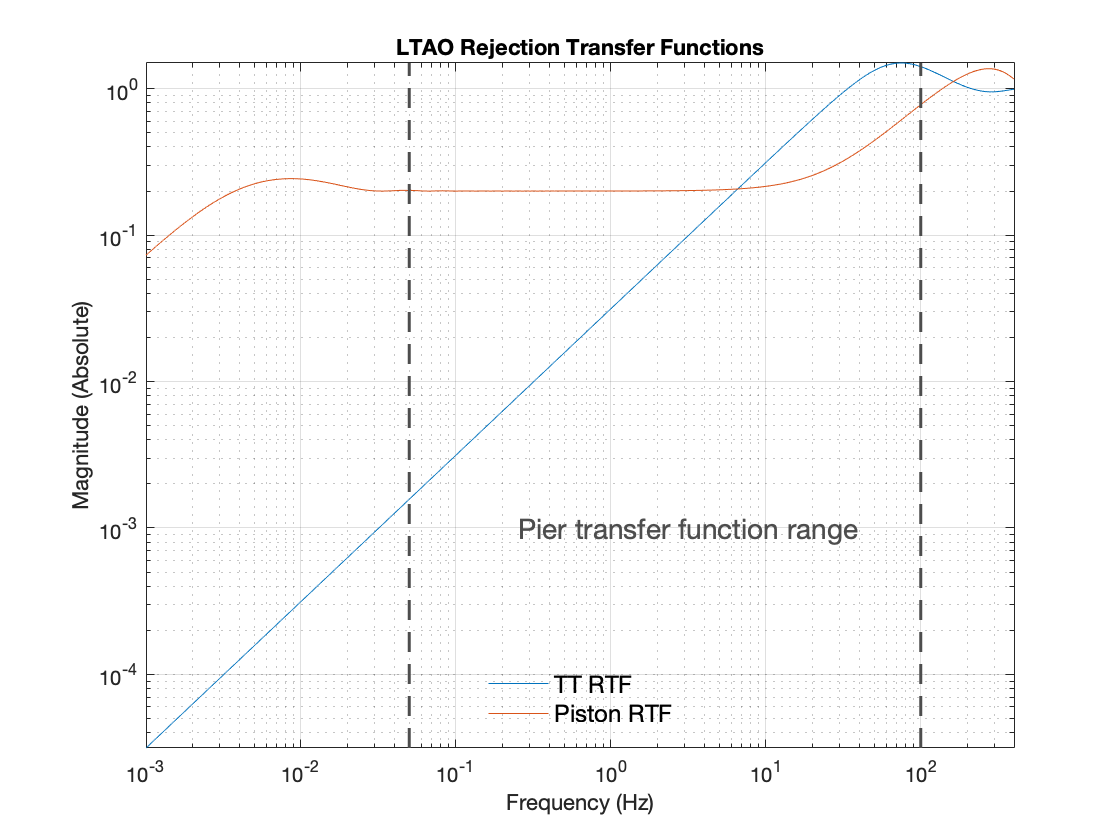

if(exist("rtf","var")), clear rtf; end
if(~true)
    rtf(1:14,1:14) = eye(14)*frd(oad_NS_rtf(om), om);  
    rtf(15:21,15:21) = eye(7)*frd(tf(1,1), om);
else    
    rtf(1:14,1:14) = eye(14)*frd(oad_AOTT_rtf(om), om);
    rtf(15:21,15:21) = eye(7)*frd(getRTF_DP(om), om);
end
rtf = frd(rtf.ResponseData, om, mount.Ts);

if(true)
    figure;
    om__ = logspace(log10(0.001), log10(400), 1001)*2*pi;
    hp(1) = loglog(om__/2/pi,abs(oad_AOTT_rtf(om__))); hold on;
    hp(2) = loglog(om__/2/pi,abs(getRTF_DP(om__)));
    axis tight;
    text(5*om(1)/2/pi,1e-3,'Pier transfer function range',...
        'Fontsize',14,'color',[.3 .3 .3]);
    yy = ylim;
    plot([om(1)/2/pi,om(1)/2/pi],yy,'--',...
        'color',[.3 .3 .3],'Linewidth',1.5);
    plot([om(end)/2/pi,om(end)/2/pi],yy,'--',...
        'color',[.3 .3 .3],'Linewidth',1.5);
    title('LTAO Rejection Transfer Functions');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (Absolute)');
    grid on; hold off;
    legend(hp,{'TT RTF','Piston RTF'},'Fontsize',12,'Location','south');
    legend box off;
end

% Conditional structure for DEBUG purposes, default value is 1.
if(1)
    % Apply rejection transfer functions
    H_pier = rtf * H_mntFB(1:21,1:6,:);
else
    H_pier = H_mntFB(1:21,1:6,:);
end

### Verification TFs

#### Pier forces to displacements (optional)

if(show_pier_TF && (first_mode == 1))
    figure;
    set(gcf,'Position',[833   323   900   450])
    set(gcf,'Name','FRF mag - Pier Forces to Displacements');
    
    subplot(121);
    for i2 = 1:3
        hb = loglog(om/2/pi, abs(squeeze(H_pier_mntFB.ResponseData(i2,i2,:))));
        hold on;
    end
    legend(strcat({'F_x->','F_y->','F_z->'},{'T_x','T_y','T_z'}),...
        'Fontsize',12,'location','northeast'); legend boxoff;
    axis tight; ylabel('Mag (Abs)'); xlabel('Freq (Hz)'); grid on; hold off;
    title('Pier forces -> Translations (nm/N)');
    
    subplot(122);
    for i2 = 4:6
        hb = loglog(om/2/pi, abs(squeeze(H_pier_mntFB.ResponseData(i2,i2,:))));
        hold on;
    end
    legend(strcat({'M_x->','M_y->','M_z->'},{'R_x','R_y','R_z'}),...
        'Fontsize',12,'location','northeast'); legend boxoff;
    axis tight; xlabel('Freq (Hz)'); grid on; hold off;
    title('Pier moments -> Rotations (urad/Nm)');
    
end

#### Pier forces to mount axes (optional)

if(false)
    figure;
    set(gcf,'Position',[833   323   900   600])
    set(gcf,'Name','FRF mag - Pier Forces to mount axes');
    mnt_ax_labels = {'AZ','EL','GIR'};
    for ik = 1:3
        subplot(3,2,1+(ik-1)*2)
        loglog(om/2/pi, abs(squeeze(H_mntFB.ResponseData(obj_sys.outputs(end).indexes(ik),1:3,:))));
        axis tight; xlabel('Freq (Hz)'); grid on; ylabel(sprintf('%s Mag (Abs)',mnt_ax_labels{ik})); hold off;
        
        legend({'F_x','F_y','F_z'},'Fontsize',12,'location','northeast'); legend boxoff;
        subplot(3,2,2*ik)
        loglog(om/2/pi, abs(squeeze(H_mntFB.ResponseData(obj_sys.outputs(end).indexes(ik),4:6,:))));
        axis tight; xlabel('Freq (Hz)'); grid on; hold off;
        legend({'M_x','M_y','M_z'},'Fontsize',12,'location','northeast'); legend boxoff;
    end
end

#### Segment Tip-tilt

Let $Y_\text{tt}(j\omega)$the 14-dimensional vector of segment tip-tilt after incorporating the effect of the rejection transfer function $$R(j\omega)$$. In the following, we present the segment tip-tilt magnitude frequency response $\breve{Y}_{\text{tt},i}(j\omega)$ for each segment $i \in \{1,2,\ldots,7\}$. The tip and tilt effects are combined in quadrature, i.e.,


$$\breve{Y}_{\text{tt},i}(j\omega) = 
\sqrt{
 \left(
Y_{\text{tt},i}(j\omega) \right) ^2 
+ \left(Y_{\text{tt},i+7}(j\omega)
\right)^2 }$$


where $Y_{\text{tt},i}(j\omega)$ denotes the $i^\text{th}$-element of $Y_\text{tt}(j\omega)$.

On the left, one has the responses for the forces; on the right, the input is the moment applied to the node representing the interface between the pier and the telescope optical structure.

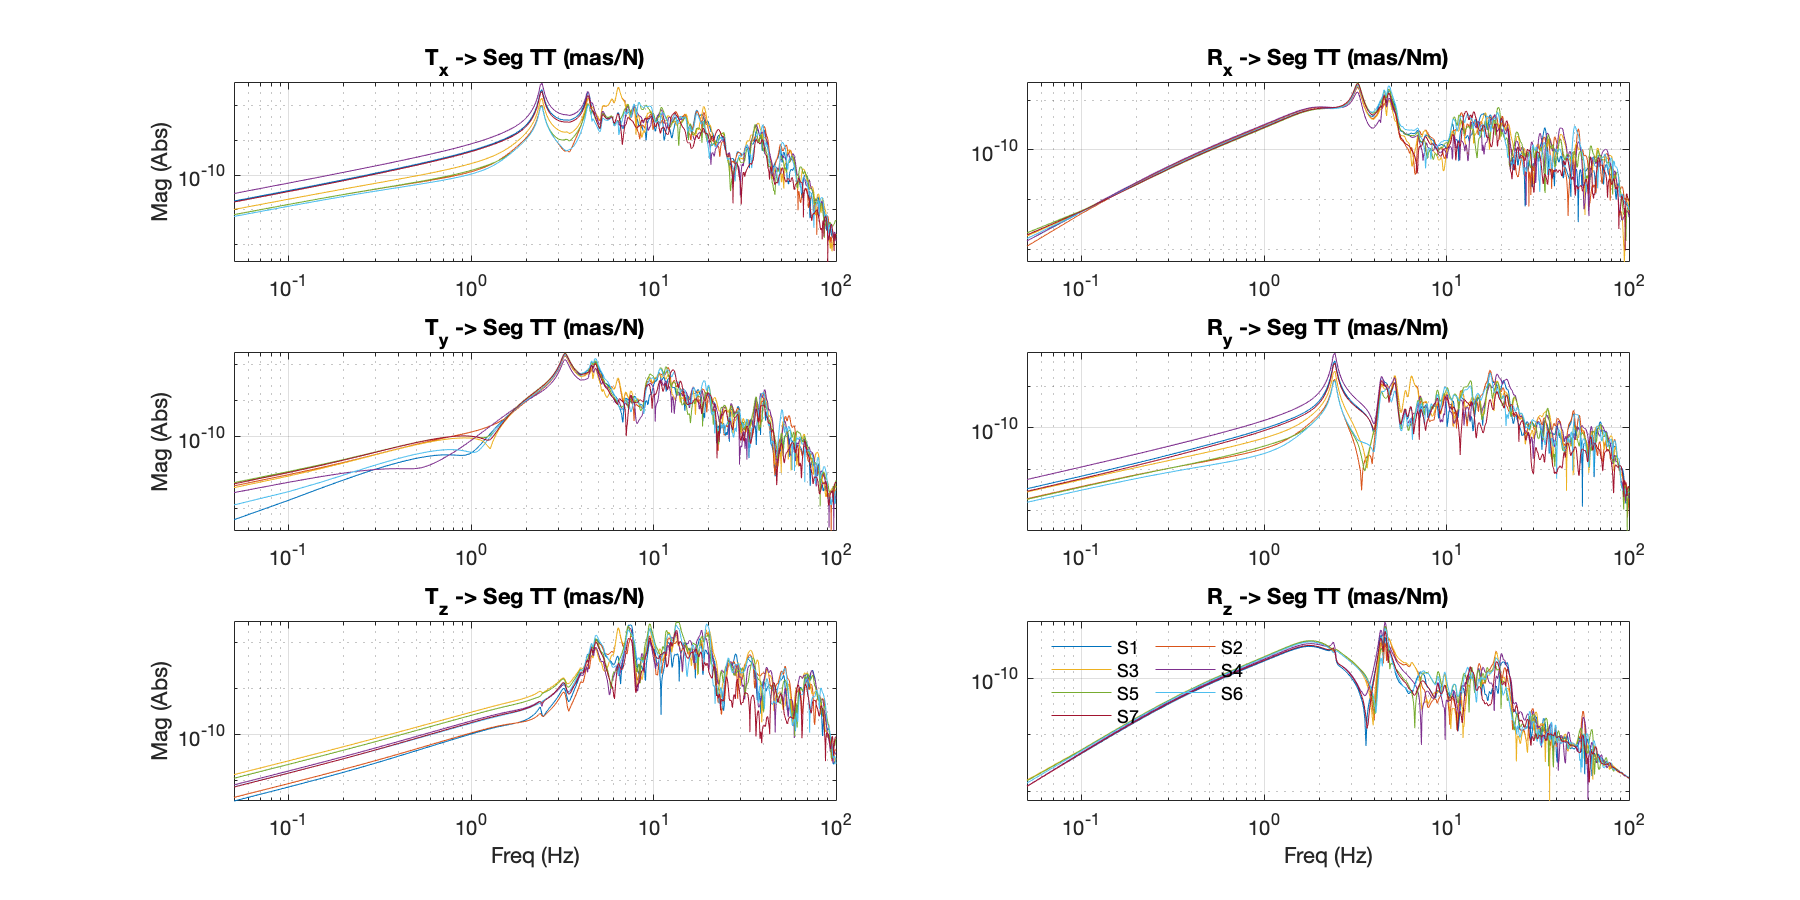

figure;
set(gcf,'Position',[833   323   900   450])
tt_frf = zeros(7,6,length(om));
for i2 = 1:6
    subplot(3,2,reposFIGs(i2));
    tt_frf(:,i2,:) = rad2mas * abs(sqrt(...
        H_pier.ResponseData(1:7,i2,:).^2 + ...
        H_pier.ResponseData((1:7)+7,i2,:).^2));
    loglog(om/2/pi, squeeze(tt_frf(:,i2,:)));
    xlim([min(om/2/pi),max(om/2/pi)]);
    
    title(sprintf('%s -> Seg TT (mas/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end
legend('S1','S2','S3','S4','S5','S6','S7',...
        'NumColumns',2,'Orientation',"horizontal",...
        'Location','northwest');
legend boxoff;

#### Segment Piston

Next, we present each segment's relative piston error induced by the pier vibrations. The ***relative*** piston error $\breve{Y}_\text{piston}(j\omega)$means that the average over the seven segments is subtracted. So,


$$\breve{Y}_{\text{piston},i}(j\omega) = 
Y_{\text{piston},i}(j\omega) - \frac{1}{7} \sum_{i=1}^7
Y_{\text{piston},i}(j\omega) ,$$


where $Y_{\text{piston},i}(j\omega)$ denotes the $i^\text{th}$-element of the 7-dimensional vector $Y_\text{piston}(j\omega)$.

As previously for the segment TT, each plot shows the response for one element of the rigid-body force/moment vector.

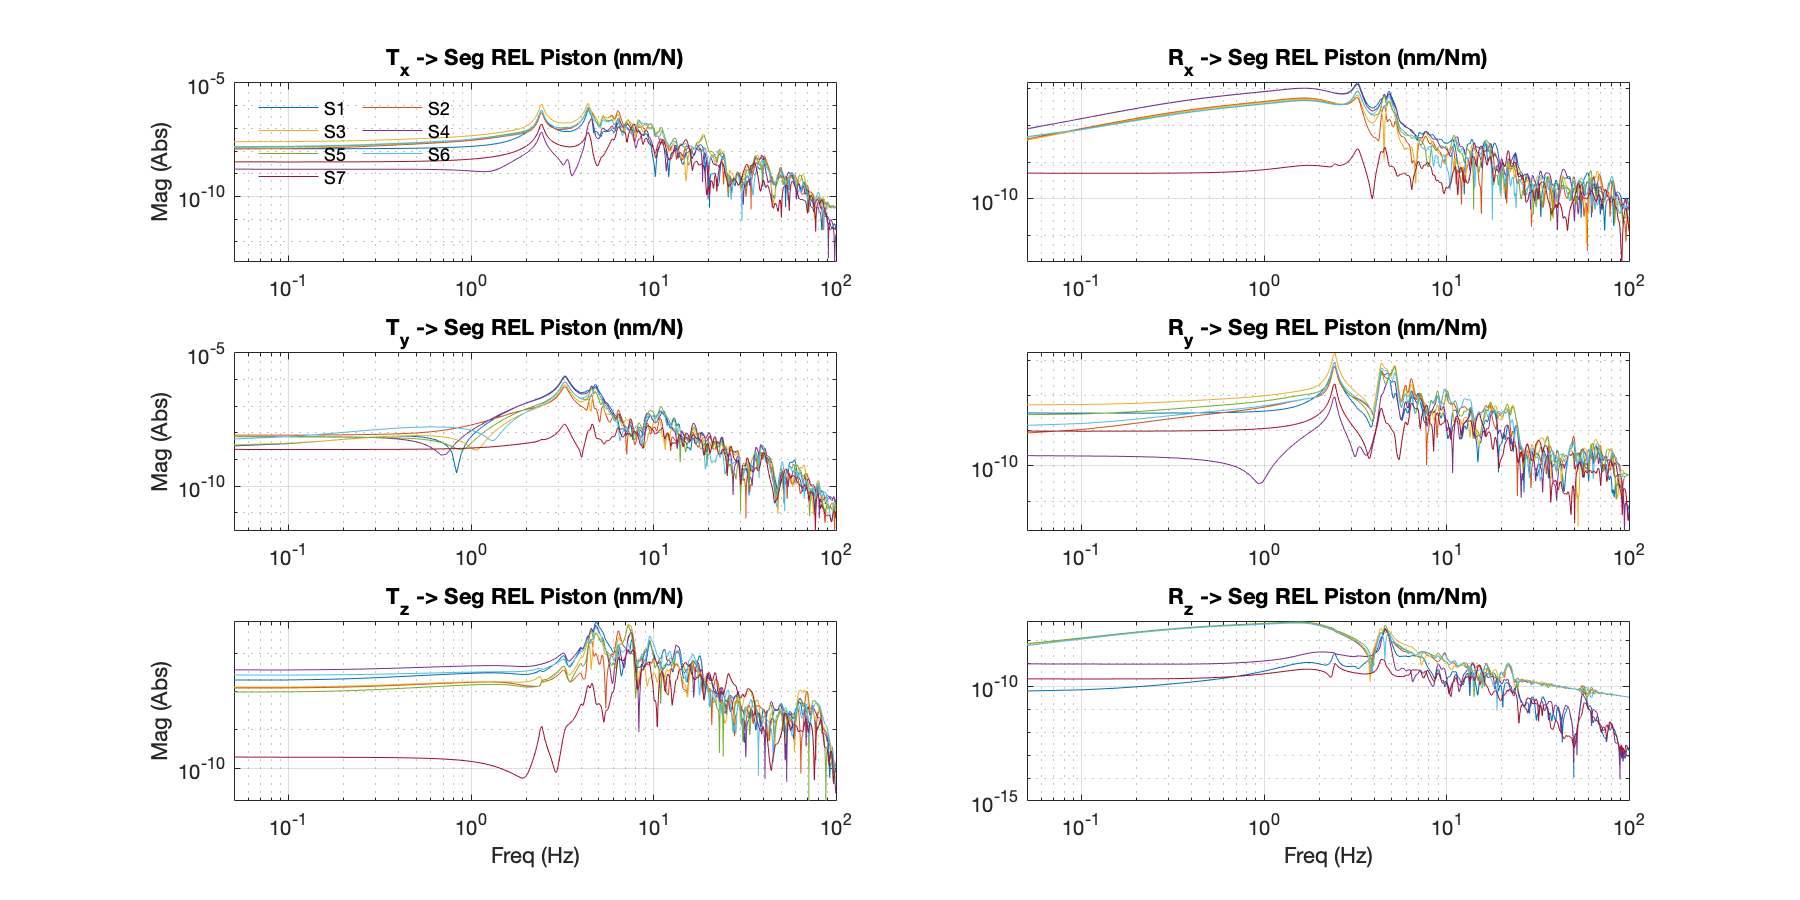

figure;
set(gcf,'Position',[833   323   900   450])
set(gcf,'Name','FRF mag - Pier 6F to Seg Piston');
piston_frf = zeros(size(tt_frf));
rel_piston_frf = zeros(size(piston_frf));
for i2 = 1:6    
    subplot(3,2,reposFIGs(i2));
    piston_frf(:,i2,:) = 1e9*abs(H_pier.ResponseData(15:21,i2,:));
    rel_piston_frf(:,i2,:) = 1e9*abs(H_pier.ResponseData(15:21,i2,:) -...
        mean(H_pier.ResponseData(15:21,i2,:)));
    loglog(om/2/pi, squeeze(rel_piston_frf(:,i2,:)));
    xlim([min(om/2/pi),max(om/2/pi)]);
    
    title(sprintf('%s -> Seg REL Piston (nm/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end
subplot(321)
legend('S1','S2','S3','S4','S5','S6','S7',...
        'NumColumns',2,'Orientation',"horizontal",...
        'Location','northwest');
legend boxoff;

### Wavefront error (WFE) responses to white-noise

One can approximate the wavefront error***** induced by a white-noise as


$$Y_\text{wf}(j\omega) =
\sqrt{ \frac{1}{7}
 \sum_{i=1}^7
 \left(\rho \breve{Y}_{\text{tt},i}(j\omega)\right) ^2 
 +
\left(\breve{Y}_{\text{piston},i}(j\omega)\right)^2
},$$


where $\rho = 10.2 \frac{\text{nm}}{\text{mas}}$ is a scaling factor. Below, we present the white-noise response $\left|Y_\text{wf}(j\omega)\right|$. That can be seen as the transfer function from the forces (and moments) applied in the node in the interface between the pier and the optical structure to the wavefront error.

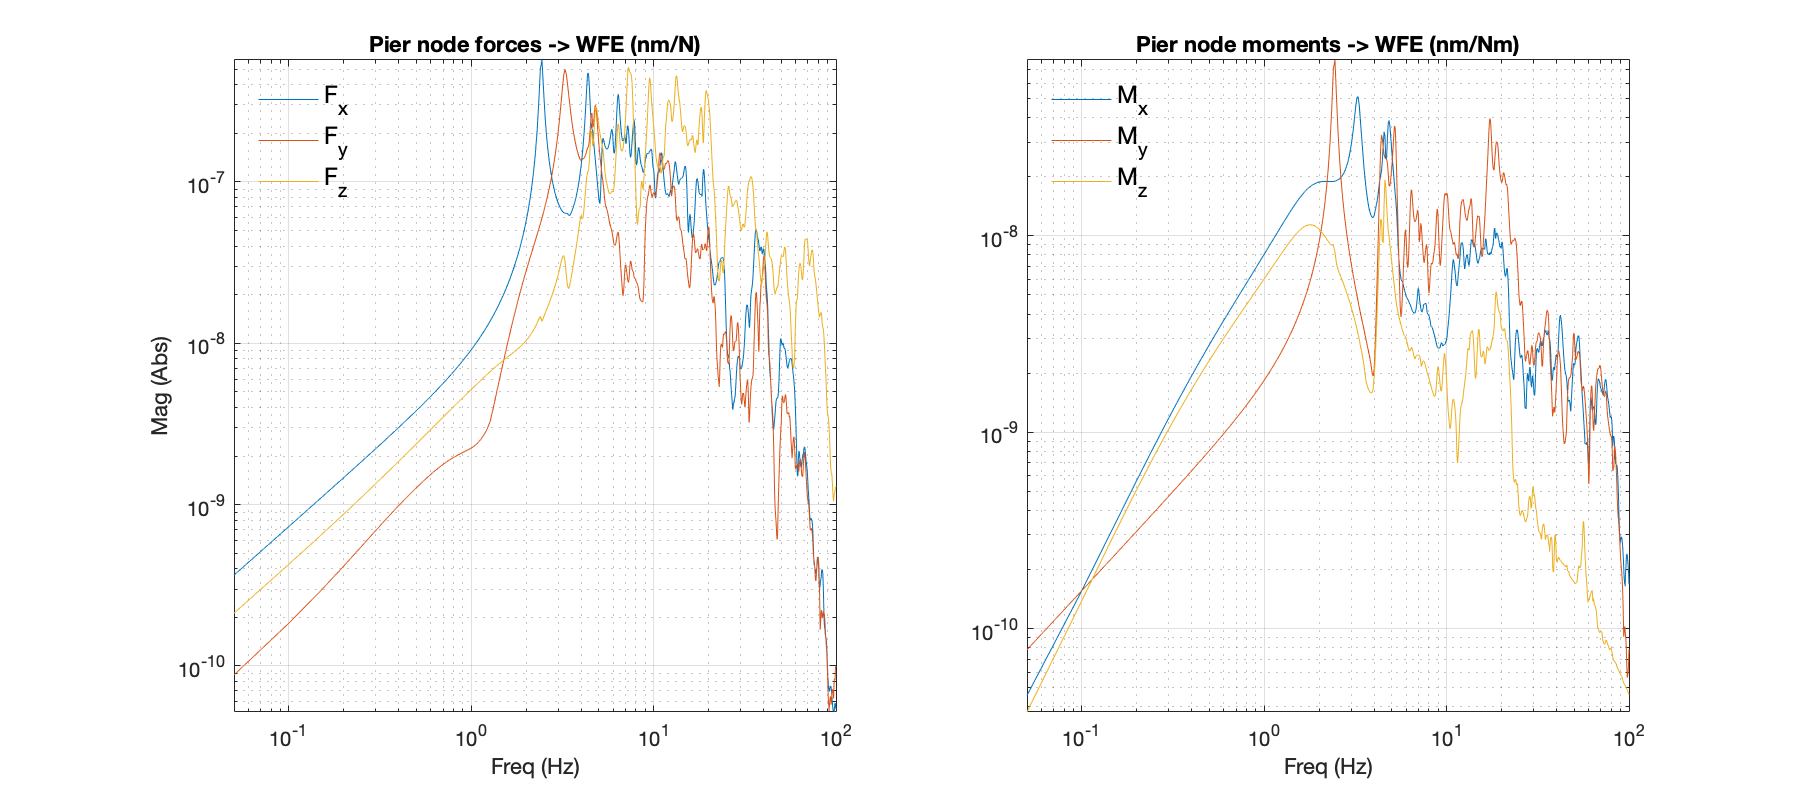

figure;
set(gcf,'Position',[833   323   900   400])

wfe = sqrt(1/7) * squeeze(sqrt((10.2*sum(tt_frf(:,1:6,:),1)).^2 +...
       sum(piston_frf(:,1:6,:) - mean(piston_frf(:,1:6,:),1)).^2));

subplot(121);
for i2 = 1:3
    loglog(om/2/pi, wfe(i2,:));
    hold on;
end
legend(plotInLabel{1:3},'Fontsize',12,'location','northwest'); legend boxoff;
axis tight; ylabel('Mag (Abs)'); xlabel('Freq (Hz)'); grid on; hold off;
title('Pier node forces -> WFE (nm/N)');

subplot(122);
for i2 = 4:6
    loglog(om/2/pi, wfe(i2,:));
    hold on;
end
legend(plotInLabel{4:6},'Fontsize',12,'location','northwest'); legend boxoff;
axis tight; xlabel('Freq (Hz)'); grid on; hold off;
title('Pier node moments -> WFE (nm/Nm)');

### WFE responses to accelerations

Vibration analysis often considers accelerations instead of forces (and moments). In the following, we perform an input transformation to obtain the transfer function from the accelerations of the pier node to the wavefront error.

`As described before`, there is no pier in the model considered. So, the azimuth track is connected rigidly to a large mass element located at: [0,0,-13.42] in the OSS00 coordinate system (CS). That large mass weights $M=2.1605 \times 10^{12}$kg and has a moment of inertia $J=2.24428 \times 10^{14}\ \text{kg}\cdot\text{m}^2$.

Ideally, the large mass motion equation reads as


$$M\ddot{x} = F_\text{node} - k_s x,$$


where $x$ is the mass position, $k_s = 8.5294 \times 10^9$N/m is the spring constant connecting the mass element to the ground, and $F_\text{node}$ is the force applied to it. Given the values of $M$and $k_s$, one can notice that the spring force plays a negligible effect on the acceleration behavior above $0.1$Hz, which is a decade above the natural frequency $\omega_\text{mass}=0.0628$rad/s. That means the approximation $M\ddot{x} = F_\text{node}$ holds for the frequency range relevant for vibration analysis, namely $\omega > 10\omega_\text{mass}$.

The simplification is also assumed for the angular motion equation. Therefore, one can use the input transformation


$$\Xi = \left[
\begin{array}{ccccc}
I_3 M & 0_{3\times3}\\
0_{3\times3} & I_3 J\end{array}
\right]$$


to convert the mass accelerations into forces. Applying the input transformation to the previous transfer function leads to the magnitude responses below.

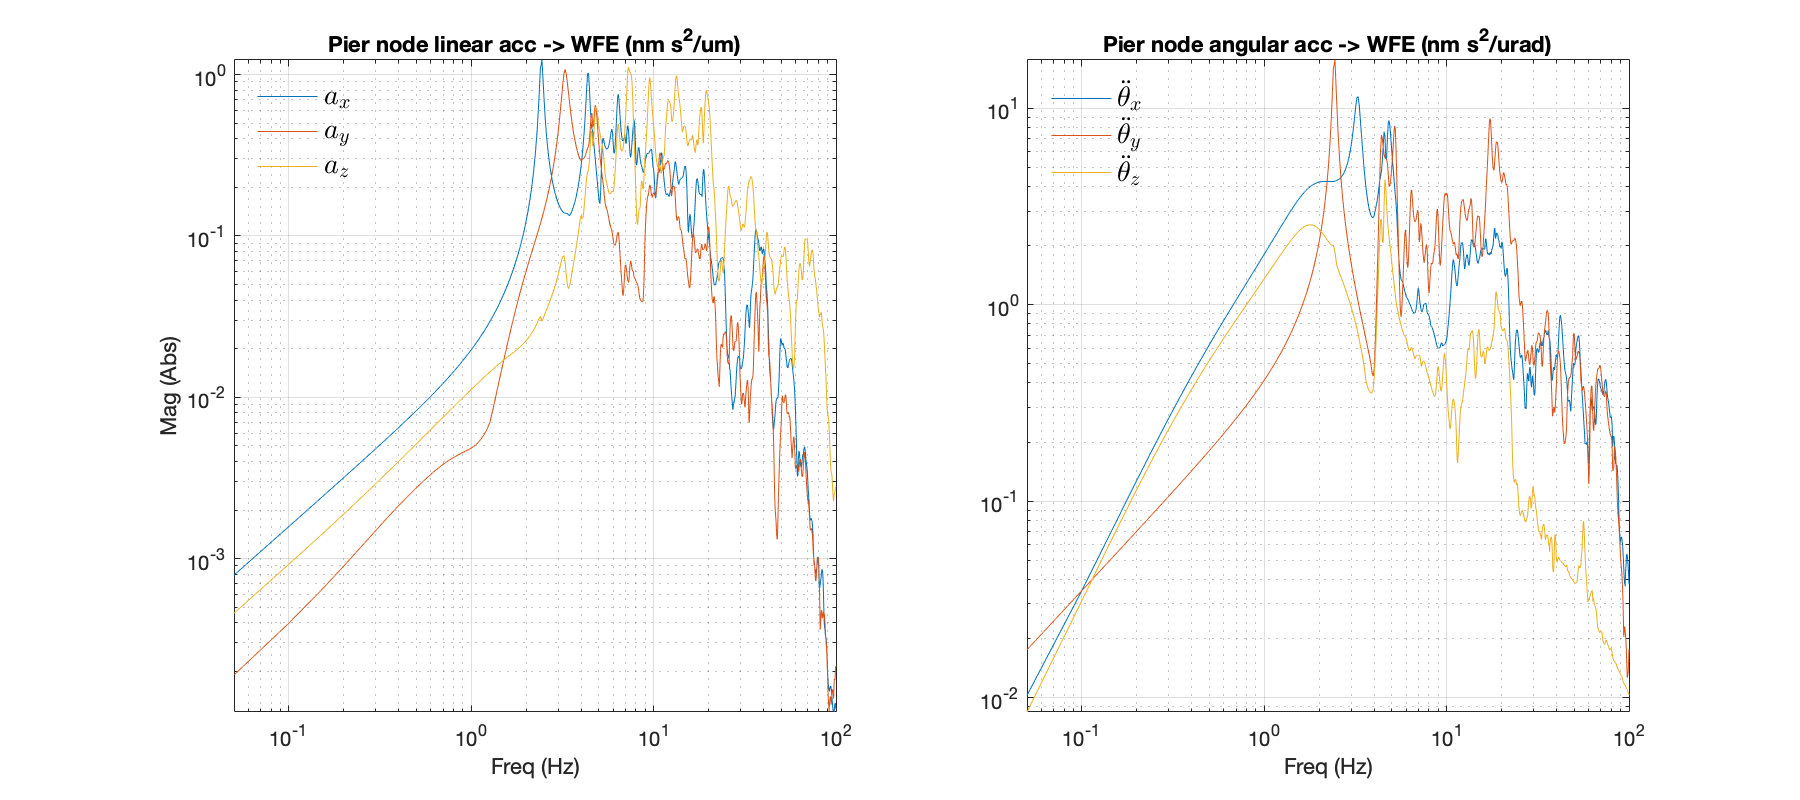

% Large mass properties
lm_mass = 2.1605e+12; % [kg]
lm_moi = 2.24428e+14; % [kg * m^2]
plotAccLabel = {'$a_x$','$a_y$','$a_z$','$\ddot{\theta}_x$','$\ddot{\theta}_y$','$\ddot{\theta}_z$'};

figure;
set(gcf,'Position',[833   323   900   400])

wfe_acc = blkdiag(eye(3)*lm_mass, eye(3)*lm_moi) * wfe;

subplot(121);
for i2 = 1:3
    loglog(om/2/pi, 1e-6*wfe_acc(i2,:));
    hold on;
end
legend(plotAccLabel{1:3},'Fontsize',14,'location','northwest','Interpreter','Latex');
legend boxoff;
axis tight; ylabel('Mag (Abs)'); xlabel('Freq (Hz)'); grid on; hold off;
title('Pier node linear acc -> WFE (nm s^2/um)');

subplot(122);
for i2 = 4:6
    loglog(om/2/pi, 1e-6*wfe_acc(i2,:));
    hold on;
end
legend(plotAccLabel{4:6},'Fontsize',14,'location','northwest','Interpreter','Latex');
legend boxoff;
axis tight; xlabel('Freq (Hz)'); grid on; hold off;
title('Pier node angular acc -> WFE (nm s^2/urad)');

### Verification data

We integrate (numerically) the wavefront frequency response magnitudes to provide some insight into the obtained transfer functions. Those values are reported in the following.

deltaF = diff(om(1:2)/2/pi);
Lacc_xyz = 1e-6* deltaF* sum(wfe_acc(1:3,:),2)';
Aacc_xyz = 1e-6* deltaF* sum(wfe_acc(4:6,:),2)';

tb1 = table(Lacc_xyz, 'Rownames',{'Cumulative effect'},...
    'VariableNames',{'Linear Acc x|y|z (nm s^2/um)'});
tb2= table(Aacc_xyz, 'Rownames',{'Cumulative effect'},...
    'VariableNames',{'Angular Acc x|y|z (nm s^2/urad)'});
disp(tb1); disp(tb2);

                         Linear Acc x|y|z (nm s^2/um)
                         ____________________________

    Cumulative effect     6.399    3.9629    13.487  

                         Angular Acc x|y|z (nm s^2/urad)
                         _______________________________

    Cumulative effect      75.186     102.5    20.579   



**Save acceleration transfer function**

readme = "The variable wfe_acc provides the magnitude of the wavefront error at the exit pupil (in nm) as a function of the rigid-body accelerations of the node representing the interface between the pier top and the azimuth track. The columns are the magnitudes for different frequencies stored in variable om (rad/s). The first three contain the magnitudes of the frequency response to the linear acceleration along axes x, y, and z according to the OSS coordinate system. The last three rows refer to the angular accelerations about x, y, and z, respectively. We assume The input accelerations are in m/sˆ2 and rad/sˆ2.";
save('pier_WFE2accTFs','readme','om','wfe_acc','FileName');

**Auxiliar functions providing the NS/LTAO RTFs (Rejection Transfer Functions)**

Function to compute the NS RTF (according to REQ-L3-OAD-35337)

function [rtf,L] = oad_NS_rtf(w)  

% PZT closed-loop bandwidth (Hz)
fz = 25;
% PZT control loop damping
delta = 0.6;
% TT loop sampling period
T = 5e-3;
% TT sensor delay
tau = 6e-3;
% TT "integral gain" - actually the considered integral gain is gi/T
gi = 0.3;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the GLAO RTF (according to REQ-L3-OAD-35398)

function [rtf,L] = oad_AOTT_rtf(w)

% LTAO RTF (according to REQ-L3-OAD-35398)
fz = 800;       % ASM closed-loop bandwidth (Hz)
delta = 0.75;   % ASM control loop damping
T = 2e-3;   % TT loop sampling period
tau = 1e-3; % TT sensor delay
gi = 0.4;   % TT "integral gain"

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the differential piston RTF

function RTF_DP = getRTF_DP(om)
    
s = sqrt(-1)*om;

%% FROM DRD rev F
omz = 800*2*pi;
dz = .75;
Tp = 30;
taup= 6/1000;
gpi = .5;
Te = 2/1000;
taue = .1/1000;
geff = .8;

num = 1 + omz^2*geff*exp(-taue*s).*(exp(-Te*s)-1)./(Te*s.*    (omz^2+2*omz*dz*s+s.^2) );
den = 1 - omz^2*gpi*exp(-taup*s).*(exp(-Tp*s)-1)./(Tp^2*s.^2.*(omz^2+2*omz*dz*s+s.^2) );
RTF_DP = num./den;
    
end